clc, clear;

Load wavelength csv file and define train set path.

wavelength = readtable('wavelengths.csv');
wavelength = table2array(wavelength(:,2));
images_filepath = 'D:\Documenti\AKO\UNI_AERO\TIROCINIO TESI\band_selection_analysis_matlab\train_data_npy\*.npy';

Create Datastore of hsi images and check exactness of procedure.

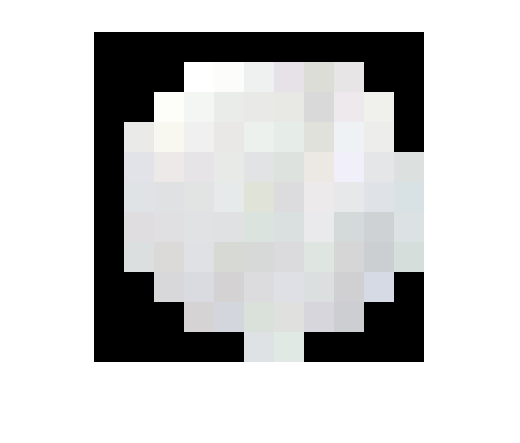

hsi_ds = fileDatastore(images_filepath, 'ReadFcn', @readNPY);
hsi_ds = transform(hsi_ds, @(x) hypercube(x, wavelength));
sample_image = preview(hsi_ds);
imshow(colorize(sample_image, 'Method', "rgb"), 'InitialMagnification', 3000);

Find most informative bands for each image.

num_train_images = 1732;
selected_bands = cell(num_train_images, 1);
i = 1;

reset(hsi_ds)

while hasdata(hsi_ds)
    hcube = read(hsi_ds);
    num_endmembers = countEndmembersHFC(hcube);
    endmembers = fippi(hcube, num_endmembers);
    [new_cube, bands] = selectBands(hcube, endmembers);
    selected_bands{i} = bands;
    i = i+1;
end

Show most informative bands for the whole dataset.

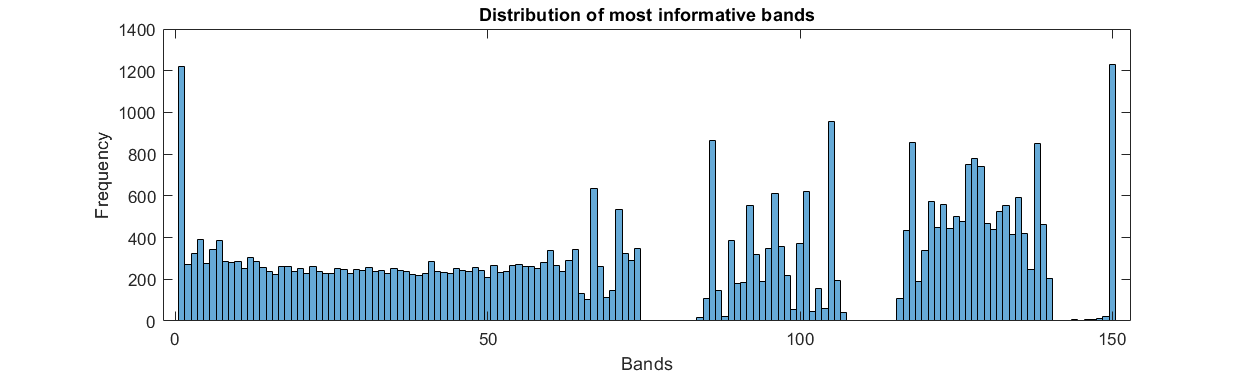

selected_bands_vec = cell2mat(selected_bands);
[count, bands] = groupcounts(selected_bands_vec);
[count, index] = sort(count, 'descend');
bands = bands(index);
figure(1)
histogram(selected_bands_vec, 'BinMethod', 'integers');

xlim([-2.0 153.0])
ylim([0 1400])
xlabel('Bands')
ylabel('Frequency')
title('Distribution of most informative bands')

set(gcf,'Position', [0 0 1000 300])

Save sorted informative band vector to npy file.

writeNPY(bands, 'informative_bands.npy')